# Victoria Strobel 

## Fahrzeugdaten laden

FzgDaten;

## Längsdynamik

### Simulation Bremsvorgang

Eingangsdaten setzen

T0 = 0.6;
T1 = 0.3;
T2 = 0.2;
ax1 = -1;
ax2 = -9;

Konfiguration der Simulation

model = 'Bremsvorgang';
load_system(model)
simIn = Simulink.SimulationInput(model);
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01');
simIn = setBlockParameter(simIn, "Bremsvorgang/Repeating_Sequence", "rep_seq_t", mat2str([0 T0 T0+T1 T0+T1+T2 20]));
simIn = setBlockParameter(simIn, "Bremsvorgang/Repeating_Sequence", "rep_seq_y", mat2str([0 0 ax1 ax2 ax2]));

Bremsvorgang simulieren

out = sim(simIn);

Daten auslesen

outputs = out.yout;
t = out.tout;
s = outputs{1}.Values.Data;
v = outputs{2}.Values.Data;
a = -outputs{3}.Values.Data;

Darstellung der Beschleunigung $a$ über $t$ 

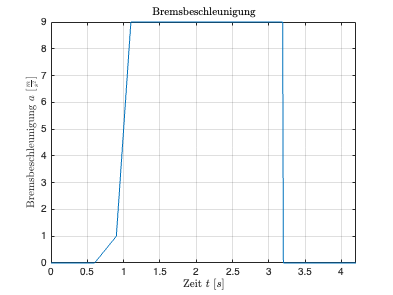

plot(t,a)
xlabel("Zeit $t$ $[s]$", 'Interpreter','latex')
ylabel('Bremsbeschleunigung $a$ $[\frac{m}{s^2}]$','Interpreter','latex')
title ('Bremsbeschleunigung', 'Interpreter','latex');
ylim([min(a), max(a)])
xlim([0, t(end)])
grid

Darstellung der Geschwindigkeit $v$ über $t$ 

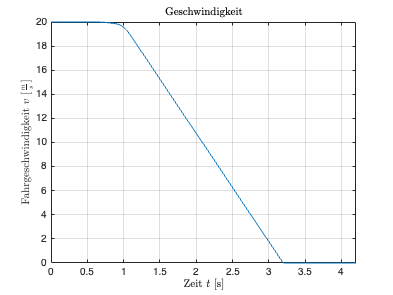

plot(t,v)
xlabel("Zeit $t$ [s]", 'Interpreter','latex')
ylabel("Fahrgeschwindigkeit $v$ $[\frac{m}{s}]$", 'Interpreter','latex')
title ('Geschwindigkeit', 'Interpreter','latex');
ylim([min(v), max(v)])
xlim([0, t(end)])
grid

Darstellung der Strecke $s$ über $t$ 

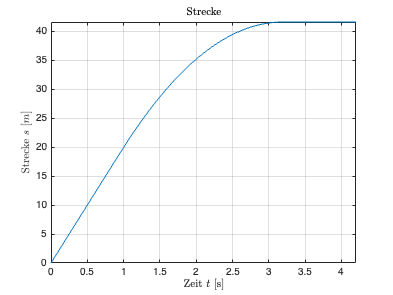

plot(t,s)
xlabel("Zeit $t$ [s]", 'Interpreter','latex')
ylabel("Strecke $s$ $[m]$", 'Interpreter','latex')
title ('Strecke', 'Interpreter','latex');
ylim([min(s), max(s)])
xlim([0, t(end)])
grid

### Tangentialkraftdiagramm

Konfiguration der Simulation

model = 'Tangentialkraftverteilung';
load_system(model)
simIn = Simulink.SimulationInput(model);
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01');

Tangentialkraftverteilung simulieren

out = sim(simIn);

Daten auslesen

outputs = out.yout;
FBh_gg = outputs{1}.Values.Data;
FBv_gg = outputs{2}.Values.Data;
psi = outputs{3}.Values.Data;
chi = outputs{4}.Values.Data;

Darstellung der Tangentialkraftverteilung

Ay = -(1-psi)/chi;
Bx = psi/chi;

figure
hold on
plot(FBv_gg, FBh_gg)
ylim([Ay, 1])
xlim([min(FBv_gg), Bx])
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

Darstellung der Linien konstanter Abbremsung $z$

for z = 0:0.2:1.0
    x = linspace(0, z);
    y = -1 * x + z;
    plot(x, y, 'r')
end

text(0.4, 0.7, 'Konstante Abbremsung', 'Color', 'r');

Darstellung der Linien konstanter Reibung $\mu$

for my = 0.6:0.4:1.0
    z = my;
    %x_z = linspace(0, z);
    %y_z = -1 * x + z;
    %plot(x, y, 'r')
    
    x = my * (1-psi + z * chi);
    y = my * (psi - z * chi);
    
    plot([0 x], [Ay, y], 'g')
    plot([x Bx], [y, 0], 'g')
    
    
    % TODO: Installierte Festabstimmung
    % plot([0 x], [0 y], Color='magenta')
end
text(0.4, -1.2, 'Konstante Reibungszahlen', 'Color', 'g');

Darstellung der Punkte $A(0, -\frac{1-\psi}{\chi})$ und $B(\frac{\psi}{\chi}, 0)$

plot(0, Ay, 'k.', 'MarkerSize', 12)
text(0.1, Ay, 'A', 'Color', 'k');
plot(Bx, 0, 'k.', 'MarkerSize', 12)
text(Bx, 0.1, 'B', 'Color', 'k');

Beschriftungen

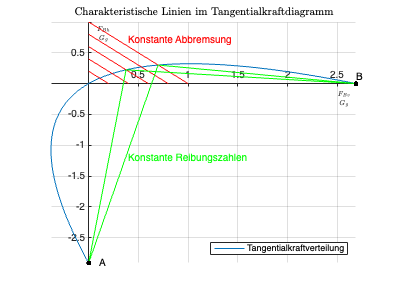

title("Charakteristische Linien im Tangentialkraftdiagramm", 'Interpreter','latex')
xlabel('$\frac{F_{Bv}}{G_g}$','Interpreter','latex');
ylabel('$\frac{F_{Bh}}{G_g}$','Interpreter','latex');
legend({'Tangentialkraftverteilung'}, 'Location', 'southeast')
grid
hold off

## Querdynamik

### Lenkradwinkelsprung  

#### Lineare Übertragungsfunktion

${C_v}^*$ und ${C_h}^*$ berechnen

Cv_stern = Cv / Fnv;
Ch_stern = Ch / Fnh;

Eigenwinkelgradient $EG$ berechnen

EG = (1/g) * (1/Cv_stern - 1/Ch_stern)

EG = 0.0058

Schwimmwinkelgradient $SG$ berechnen

SG = 1/(g * Ch_stern)

SG = 0.0050

Geschwindigkeit $v=60\frac{km}{h}$ in $m/s$ umwandeln

v = 60 / 3.6;

Ungedämpfte Eigenfrequenz $\omega_0^2$ und $\omega_0$ berechnen

omega_0_quadrat_1 = (m * v^2 * (Ch * Lh - Cv * Lv) + Cv * Ch * L^2) / (J  * m * v^2);
omega_0_quadrat_2 = (m * Lv * Lh) / (SG * J * L *v^2) * (L + EG * v^2)/(EG + SG);
omega_0_quadrat_3 = (m * g * Lv * Lh) / (J * L * v^2) * (v^2 * (Ch_stern - Cv_stern) + g * L * Cv_stern * Ch_stern);

tolerance = 10^-13;
if abs(omega_0_quadrat_3-omega_0_quadrat_2) < tolerance && abs(omega_0_quadrat_1-omega_0_quadrat_2) < tolerance
    fprintf("Alle Berechnungs-Optionen ergeben den gleichen Wert %f", omega_0_quadrat_1)
end

Alle Berechnungs-Optionen ergeben den gleichen Wert 115.161290


omega_0 = sqrt(omega_0_quadrat_1)

omega_0 = 10.7313

Zählerzeitkonstante $T_Z$ berechnen

Tz_1 = v * SG;
Tz_2 = (m * v *Lv) / (Ch * L);
Tz_3 = v / (Ch_stern * g);
if abs(Tz_3-Tz_2) < tolerance && abs(Tz_1-Tz_2) < tolerance
    fprintf("Alle Berechnungs-Optionen ergeben den gleichen Wert %f", Tz_1)
end

Alle Berechnungs-Optionen ergeben den gleichen Wert 0.082667

Abklingkonstante $2\sigma$ und $\sigma$ berechnen

zwei_sigma_1 = (m * (Cv * Lv^2 + Ch * Lh^2) + J * (Cv + Ch)) / (J * m * v);
zwei_sigma_2 = (m * Lv * Lh * (EG * Lh + SG * L) + J * (EG * Lv + SG * L)) / (J * SG * L * v * (EG + SG));
zwei_sigma_3 = g * (m * Lv * Lh * (Cv_stern * Lv + Ch_stern * Lh) + J * (Cv_stern * Lh + Ch_stern * Lv)) / (J * L *v);
if abs(zwei_sigma_3-zwei_sigma_2) < tolerance && abs(zwei_sigma_1-zwei_sigma_2) < tolerance
    fprintf("Alle Berechnungs-Optionen ergeben den gleichen Wert %f", zwei_sigma_1)
end

Alle Berechnungs-Optionen ergeben den gleichen Wert 18.426797

sigma = zwei_sigma_1 / 2

sigma = 9.2134

Stationäre Gierverstärkung $K$/$\omega_0^2$  berechnen

K_omega_0_quadrat_1 = (Cv * Ch *L) / (J * m * v * omega_0_quadrat_1);
K_omega_0_quadrat_2 = v / (L + EG * v^2);
K_omega_0_quadrat_3 = (Cv_stern * Ch_stern * g^2 * Lv * Lh * m)/(J * L * v * omega_0_quadrat_1);
if abs(K_omega_0_quadrat_3-K_omega_0_quadrat_2) < tolerance && abs(K_omega_0_quadrat_1-K_omega_0_quadrat_2) < tolerance
    fprintf("Alle Berechnungs-Optionen ergeben den gleichen Wert %f", K_omega_0_quadrat_1)
end

Alle Berechnungs-Optionen ergeben den gleichen Wert 3.781513

Gierdämpfungsmaß $D$ berechnen

D_gier_1 = sigma / omega_0

D_gier_1 = 0.8586

$K$/$\omega_0^2$ , $2\sigma$, $\sigma$, $\omega_0^2$, $\omega_0$ und $D$ in Abhängigkeit von der Geschwindigkeit $v$ berechnen

v_kmh = linspace(0, 250, 251);
v = v_kmh ./ 3.6;
zwei_sigma = (m * (Cv * Lv^2 + Ch * Lh^2) + J * (Cv + Ch)) ./ (J * m * v);
sigma = zwei_sigma / 2;
omega_0_quadrat = (m .* v.^2 * (Ch * Lh - Cv * Lv) + Cv * Ch * L^2) ./ (J * m .* v.^2);
omega_0 = sqrt(omega_0_quadrat);
K_omega_0_quadrat = (Cv * Ch * L) ./ (J .* m .* v .* omega_0_quadrat);
D_gier = sigma ./ omega_0;

Ungedämpfte Eigenfrequenz $\nu_0$ berechnen

ny_0 = omega_0 / (2 * pi);

Gedämpfte Eigenfrequenz $\nu$ berechnen

ny = ny_0 .* sqrt(1 - D_gier.^2);

Darstellung der ungedämpften und gedämpften Eigenfrequenz über der Geschwindigkeit

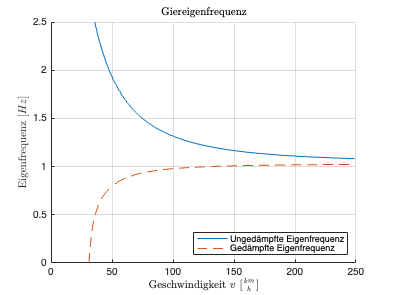

index = find(real(ny) > 0, 1);
figure
hold on
plot(real(v_kmh(index-1:250)), real(ny_0(index-1:250)), 'DisplayName', 'Ungedämpfte Eigenfrequenz')
plot(real(v_kmh(index-1:250)), real(ny(index-1:250)), '--', 'DisplayName', 'Gedämpfte Eigenfrequenz')
title('Giereigenfrequenz', 'Interpreter','latex')
ylim([0 2.5])
xlim([0 250])
xlabel('Geschwindigkeit $v$ $[\frac{km}{h}]$','Interpreter','latex');
ylabel('Eigenfrequenz $[Hz$]','interpreter','latex')
grid
legend('show', 'Location', 'southeast');
hold off

Darstellung des Dämpfungsmaßes über der Geschwindigkeit

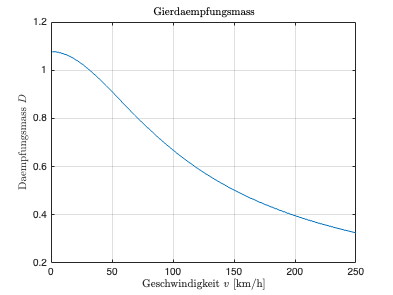

plot(v_kmh, D_gier)
title('Gierdaempfungsmass', 'Interpreter','latex')
xlabel('Geschwindigkeit $v$ [km/h]','Interpreter','latex');
ylabel('Daempfungsmass $D$','interpreter','latex')
ylim([0.2 1.2])
yticks(0.2:0.2:1.2)
xlim([0 250])
grid

#### Sprungantwort

Übetragungsfunktion $G(s)$ definieren


$$G(s) = \frac{\dot{\psi}(s)}{\delta(s)} = K \cdot \frac{1 + T_zs}{s^2+2\sigma s + \omega_0^2}$$


v = 60 / 3.6;
K = (Ch*Cv*L)/(J*m*v);
tf_gs = tf([Tz_1*K K], [1 zwei_sigma_1, omega_0_quadrat_1]);

Sprungantwort berechnen

config = RespConfig('Amplitude', 45/iS);
[y_step, t_step] = step(tf_gs, 1.0, config);

#### Nichtlineares Einspurmodell  

model = 'Lenkradwinkelsprung';
load_system(model)
simIn = Simulink.SimulationInput(model);

*Hinweis: Alle Modellparameter, die mit *setModelParameter() *gesetzt werden können, lassen sich folgendermaßen ermitteln:*

Konfiguration der Simulation: $t_\text{Start}=0$, $t_\text{Stop}=t_{\rm end}$, Integration mit fester Zeitschrittweite $\Delta t=0.01$  

tend = 1;
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01',...
    'StartTime','0',...
    'StopTime',num2str(tend));

Konfiguration des Lenkradwinkelsprungs mit $\delta_\text{H}=45\degree $ und $v=60\text{ km/h}$

dH = 45;
v = 60;
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/dH","Time",'0');         % Sprung bei t=0
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/dH","After",string(dH)); % Sprunghöhe in Grad
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/v","Value",string(v));   % Konstante Geschwindigkeit in km/h

Konfiguration der Pacejka-Blöcke mit den Schräglaufsteifikgeiten $C_\text v$, $C_\text h$ und den Achslasten $F_\text{nv}$, $F_\text{nh}$

simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Cv", "Value",string(Cv));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Ch", "Value",string(Ch));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Fnv","Value",string(Fnv));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Fnh","Value",string(Fnh));
applyToModel(simIn) % nicht unbedingt notwendig

Lenkradwinkelsprung simulieren

out = sim(simIn);

Daten auslesen

outputs = out.yout;
outputPsip = getElement(outputs,'psip');
t    = outputPsip.Values.Time;
psip = outputPsip.Values.Data;

Darstellung der Giergeschwindigkeit $\dot\psi$ über $t$ des nichtlinearen und des linearen Einspurmodells 

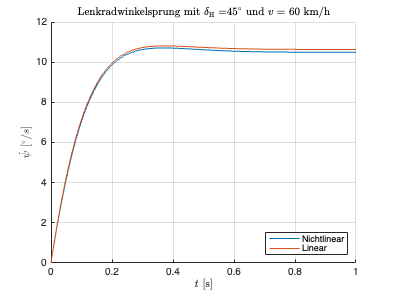

figure
hold on
plot(t,psip)
plot(t_step, y_step)
xlabel('$t$ [s]','Interpreter','latex');
ylabel('$\dot{\psi}$ $[^\circ/s]$','interpreter','latex')
title (['Lenkradwinkelsprung mit $\delta_{\rm H} = $' num2str(dH) '$^\circ$ und $v =$ ' num2str(v) ' km/h'] , 'Interpreter','latex'  )
legend('Nichtlinear','Linear','Location','southeast')
grid
hold off

### Seitenkräfte

#### Neutral steuerndes Einspurmodell

Es gilt $EG=0$. Für die Schräglaufsteifigkeit $C_{h,0}$ gilt damit: 


$$C_{h,0} = F_{nh} * {C_h}^* = F_{nh} * \frac{1}{\frac{F_{nv}}{C_v} - g * 0} = F_{nh} * \frac{1}{\frac{F_{nv}}{C_v}} = F_{nh} * \frac{C_v}{F_{nv}}$$


Ch_0 = Fnh * (Cv / Fnv)

Ch_0 = 6.9231e+04


$$C_{h,0} = 69231 \frac{N}{rad}$$


#### Übersteuerndes Einspurmodell

Es gilt $EG<0$. Für die Schräglaufsteifigkeit $C_{h,i}$ gilt damit: 

$C_{h,i} = F_{nh} * \frac{1}{\frac{F_{nv}}{C_v} - g *EG}$ und $C_{h,i} = B_h * F_{nh} * C * D$ mit $B_h \in [4...12]$

Durch Gleichsetzen und Umformen der beiden Gleichungen folgt:


$$EG = \frac{\frac{F_{nv}}{C_v} - \frac{1}{B_h*C*D}}{g}$$


Aus der Formel folgt, dass $B_h$ für einen möglichst weit im Negativ liegenden Eigenlenkwinkelgradienten EG möglichst klein sein muss. Daher gilt $B_h = 4$:

EG_i = ((Fnv / Cv) - 1 / (4 * C * D)) / g

EG_i = -0.0027

Für die Schräglaufsteifigkeit $C_{h,i}$ gilt damit:

Ch_i = Fnh * (1 / (Fnv / Cv - g * EG_i))

Ch_i = 5.5470e+04


$$C_{h,i} = 55470 \frac{N}{rad}$$


#### Darstellung der Seitenkräfte

Berechnung der Seitenkräfte für die Achslasten $F_{nv}$ und $F_{nh}$ und die Schräglaufsteifigkeiten $C_v$, $C_h$, $C_{h,0}$ und $C_{h,i}$ in Abhängigkeit vom Schräglaufwinkel im Bereich $\alpha \in [0^\circ...20^\circ]$

alpha = linspace(0,20,100);
Fs_v = Pacejka(alpha, Fnv, Cv, C, D, E);
Fs_h = Pacejka(alpha, Fnh, Ch, C, D, E);
Fs_h_0 = Pacejka(alpha, Fnh, Ch_0, C, D, E);
Fs_h_i = Pacejka(alpha, Fnh, Ch_i, C, D, E);

Darstellung der Seitenlkäfte $F_s$ über dem Schräglaufwinkel $\alpha$

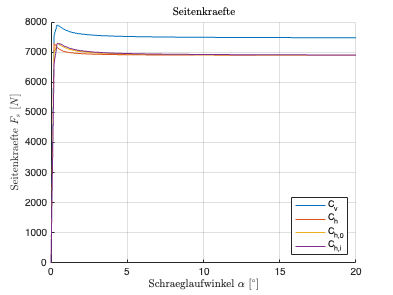

figure
hold on
plot(alpha, Fs_v, "DisplayName", "C_v")
plot(alpha, Fs_h, "DisplayName", "C_h")
plot(alpha, Fs_h_0, "DisplayName", "C_{h,0}")
plot(alpha, Fs_h_i, "DisplayName", "C_{h,i}")
title('Seitenkraefte', 'Interpreter', 'latex')
xlabel('Schraeglaufwinkel $\alpha$ $[^\circ]$', 'Interpreter', 'latex')
ylabel('Seitenkraefte $F_s$ $[N]$', 'Interpreter', 'latex')
grid
legend('show', 'Location', 'southeast')
hold off

### Gesteuerte stationäre Kreisfahrt